Problem 1

- Deterministic - Gradiant

clear;
syms x;
f = 1-exp(-x^2)-(2*exp(-(x-3)^2))-exp(-(x-6)^2);
g = diff(f);

delta = 0.1;
k = 1;
x_val(1) = unifrnd(-1,7);
while k<1000
    x = x_val(k);
    grad = double(subs(g));
    x_val(k+1) = x_val(k) - (delta*grad);
    k = k+1;
end

Plotting objective function

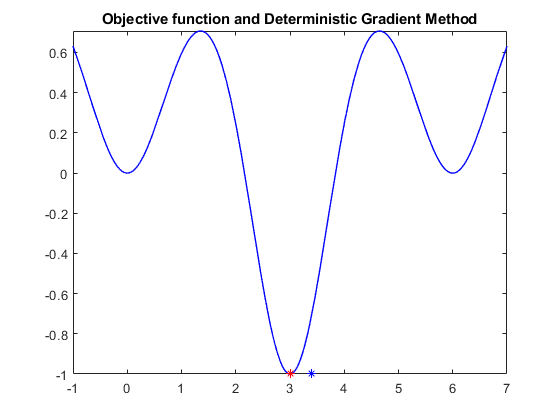

figure(1);
fplot(f,[-1,7],'b','linewidth',1);
hold on;
plot(x_val(1),-1,'b*');
plot(x_val(end),-1,'r*');
x = x_val(end);
plot([x_val(end) x_val(end)],[-1 double(subs(f))],'r--');
title('Objective function and Deterministic Gradient Method');

Plotting convergence of iteration

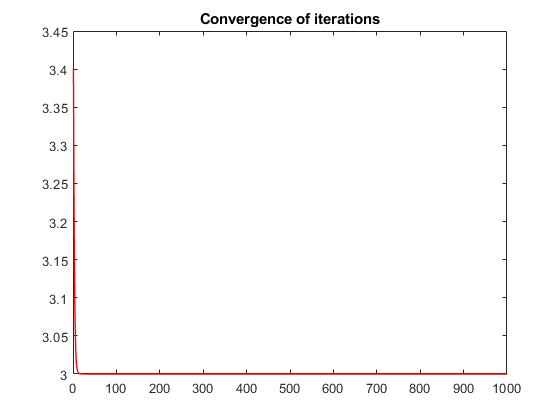

figure(2);
plot(x_val,'r','linewidth',1);
title('Convergence of iterations');

- Stochastic Gradiant Approach

clear;
syms x;
f = 1-exp(-x^2)-(2*exp(-(x-3)^2))-exp(-(x-6)^2);
g = diff(f);

delta = 0.1;
T = 0.1;
k = 1;
x_val(1) = unifrnd(-1,7);
while k<1000
    x = x_val(k);
    grad = double(subs(g));
    x_val(k+1) = x_val(k) - (delta*grad) + (sqrt(2*delta*T)*randn);
    k = k+1;
end

Plotting objective function

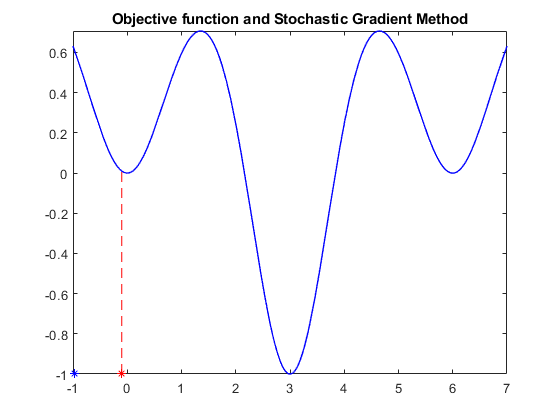

figure(3);
clf;

fplot(f,[-1,7],'b','linewidth',1);
hold on;
plot(x_val(1),-1,'b*');
plot(x_val(end),-1,'r*');
x = x_val(end);
plot([x_val(end) x_val(end)],[-1 double(subs(f))],'r--');
title('Objective function and Stochastic Gradient Method');

Plotting convergence of iteration

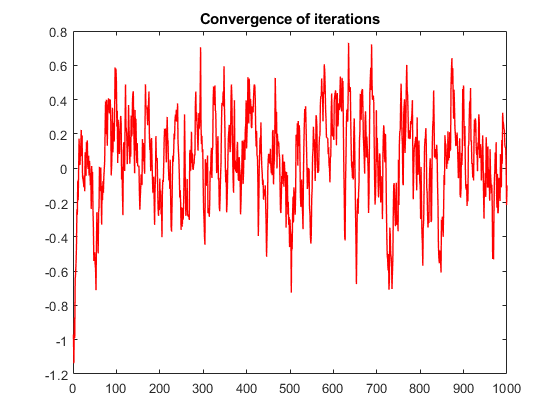

figure(4)
plot(x_val,'r','linewidth',1);
title('Convergence of iterations');

- Simulated Annealing

clear;
syms x;
f = 1-exp(-x^2)-(2*exp(-(x-3)^2))-exp(-(x-6)^2);

T = 0.1;
alpha = 0.99;
k = 1;
x_val(1) = unifrnd(-1,7);
while k<1000
    while k~=0
        yk = x_val(k) + (sqrt(T)*randn);
        if yk>=-1 && yk<=7
            break;
        end
    end
    
    x = x_val(k);
    Exk = double(subs(f));
    x = yk;
    Eyk = double(subs(f));
    rho = min(exp(-(Eyk-Exk)/T),1);
    if rho>rand()
        x_val(k+1) = yk;
    else
        x_val(k+1) = x_val(k);
    end
    T = T*alpha;
    k = k+1;
end

Plotting objective function

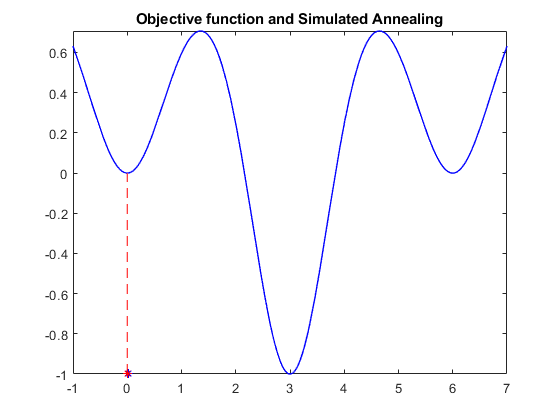

figure(5);
clf;

fplot(f,[-1,7],'b','linewidth',1);
hold on;
plot(x_val(1),-1,'b*');
plot(x_val(end),-1,'r*');
x = x_val(end);
plot([x_val(end) x_val(end)],[-1 double(subs(f))],'r--');
title('Objective function and Simulated Annealing');

Plotting convergence of iteration

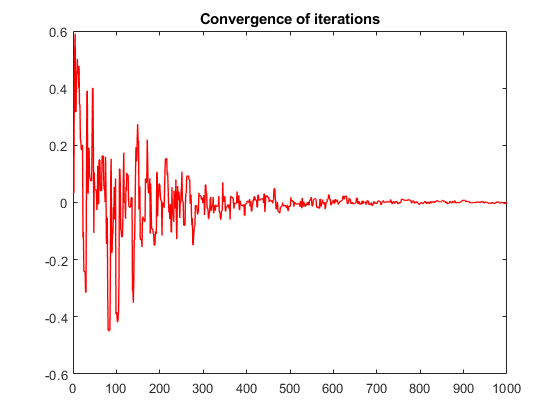

figure(6);
plot(x_val,'r','linewidth',1);
title('Convergence of iterations');

Problem 2

clear;
f = @(x,y) ((x*sin(20*y))+(y*sin(20*x)))^2*cosh(sin(10*x)*x) + ((x*cos(10*y))-(y*sin(10*x)))^2*cosh(cos(20*y)*y) + (0.01*((x^2)+(y^2)));

T = 0.01;
alpha = 0.995;
k = 1;
xy_val(:,1) = unifrnd(-1,1,[2,1]);
while k<1000
    while k~=0
        zk = xy_val(:,k) + (sqrt(T)*mvnrnd([0 0],eye(2))');
        if zk(1,1)>=-1 && zk(2,1)>=-1 && zk(1,1)<=1 && zk(2,1)<=1
            break;
        end
    end
    
    Ezk = f(zk(1,1),zk(2,1));
    Ek = f(xy_val(1,k),xy_val(2,k));
    rho = min(exp(-(Ezk-Ek)/T),1);
    if rho > rand()
        xy_val(:,k+1) = zk;
    else
        xy_val(:,k+1) = xy_val(:,k);
    end
    T = T*alpha;
    k = k+1;
end

Plotting objective function

figure(7);
clf;
fsurf(f,[-1 1]);

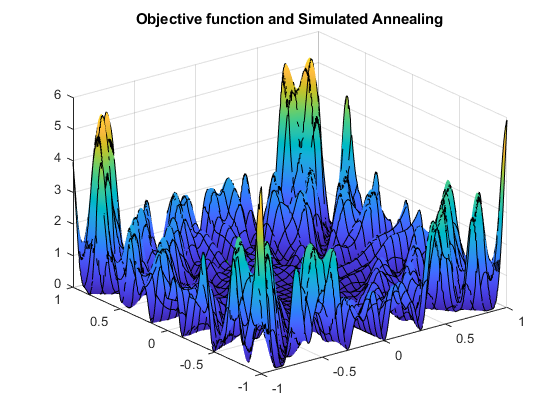

hold on;
plot3(xy_val(1,1),xy_val(2,1),f(xy_val(1,1),xy_val(2,1)),'g.','MarkerSize',20);
plot3(xy_val(1,end),xy_val(2,end),f(xy_val(1,end),xy_val(2,end)),'r.','MarkerSize',20);
title('Objective function and Simulated Annealing');

Plotting convergence of iteration

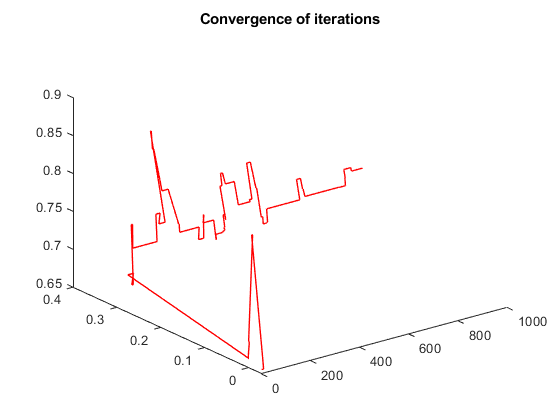

figure(8)
s = size(xy_val);
plot3(1:s(2),xy_val(1,:),xy_val(2,:),'r','linewidth',1);
title('Convergence of iterations');